## Proyecto 1 - Probabilidad y estadística

### Nicolas Vargas Flores 1001368855

#### Universidad de Antioquia 2024

datos = readtable("nutrition_elderly.csv");

### Parte 1 - Procedimiento

        **a) ¿Cuál es la población bajo estudio?**

generos = datos.gender == 1; % Esto da como resultado un logical array

hombres = 0;
mujeres = 0;

for i = 1:length(generos)
    if generos(i) == 1
        hombres = hombres + 1;
    else
        mujeres = mujeres + 1;
    end
end

hombres % Total de hombres

hombres = 85

mujeres % Total de mujeres

mujeres = 141

total_muestra = hombres + mujeres

total_muestra = 226


edades = datos.age; % Esto da como resultado un array con las edades
min_edad = min(edades)

min_edad = 65

max_edad = max(edades)

max_edad = 91

La población corresponde a personas adultas mayores entres los 65 y 91 años a los cuales se les hizo un seguimiento nutricional.

       ** b) ¿La anterior información corresponde a una población o a una muestra?**

La anterior información corresponde a una muestra. Específicamente es una muestra de 85 hombres y 141 mujeres para un total de 226 personas mayores involucradas en el estudio.

        **c) ¿Cuántas variables hay en el conjunto de datos?**

variables_cantidad = length(datos.Properties.VariableNames)

variables_cantidad = 13

En este estudio se contemplaron 13 variables diferentes.

        **d)  Realice una tabla con los tipos de características que tiene cada dataset.**

variables = datos.Properties.VariableNames;
tipos = varfun(@class,datos,'OutputFormat','cell');

tabla_tipos = table(variables', tipos', 'VariableNames', {'NombreVariable', 'Tipo'})

tabla_tipos = 13×2 table
       NombreVariable          Tipo   
    ____________________    __________

    {'gender'          }    {'double'}
    {'situation'       }    {'double'}
    {'tea'             }    {'double'}
    {'coffee'          }    {'double'}
    {'height'          }    {'double'}
    {'weight'          }    {'double'}
    {'age'             }    {'double'}
    {'meat'            }    {'double'}
    {'fish'            }    {'double'}
    {'raw_fruit'       }    {'double'}
    {'cooked_fruit_veg'}    {'double'}
    {'chocol'          }    {'double'}
    {'fat'             }    {'double'}


`varfun(@class,datos,'OutputFormat','cell')` aplica la función `class` a cada variable en la tabla `datos` y devuelve los tipos de datos en una celda

Observe que la tabla de los tipos de característica de este dataset son todo datos tipo ***double, ***este tipo de datos hace referencia a los ***double precision*** que son números de alta precisión; numeros flotantes, también conocidos como ***floats*** o decimales

Lo anterior tiene coherencia pues las respuestas de todos los participantes del estudio se almacenaron como números que van del 0 al 5, cantidade (kg, numero de tazas, cm, años) u opciones binarias entre 1 y 2.

### Parte 2 - Análisis descriptivo

-  Realizar las tablas de frecuencia de los datos a los que aplica y elija como presentar  los gráficos más apropiados según el tipo de variable.

**Tabla de frecuencias para la variable gender:**


Valores que toma la variable 


     1
     2



Frecuencia 


    85
   141



Frecuencia relativa (%) 


   37.6106
   62.3894



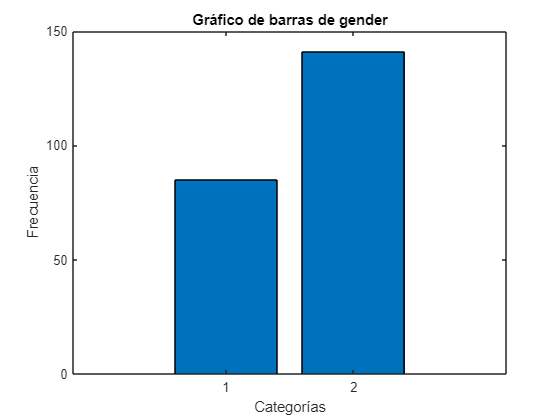

**Tabla de frecuencias para la variable situation:**


Valores que toma la variable 


     1
     2
     3



Frecuencia 


    98
   119
     9



Frecuencia relativa (%) 


   43.3628
   52.6549
    3.9823



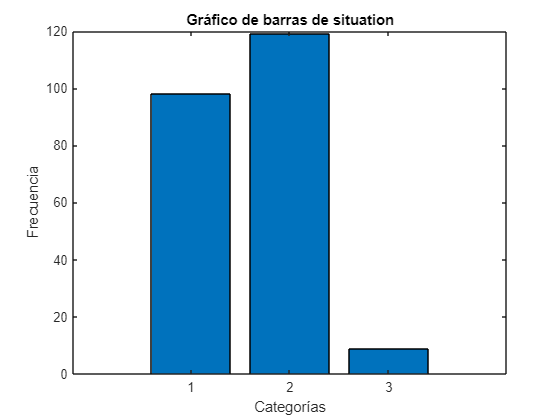

**Tabla de frecuencias para la variable tea:**


Valor mínimo de tea: 0


Valor máximo de tea: 10


Media de tea: 0.71239


Mediana de tea: 0


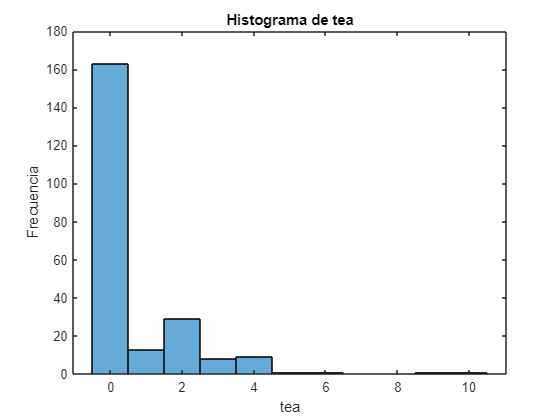

**Tabla de frecuencias para la variable coffee:**


Valor mínimo de coffee: 0


Valor máximo de coffee: 5


Media de coffee: 1.6195


Mediana de coffee: 2


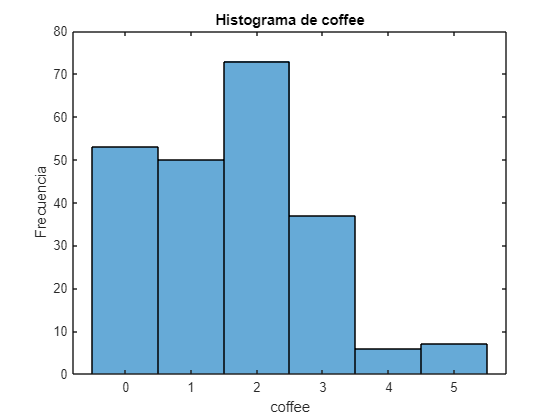

**Tabla de frecuencias para la variable height:**


Valor mínimo de height: 140


Valor máximo de height: 188


Media de height: 163.9602


Mediana de height: 163


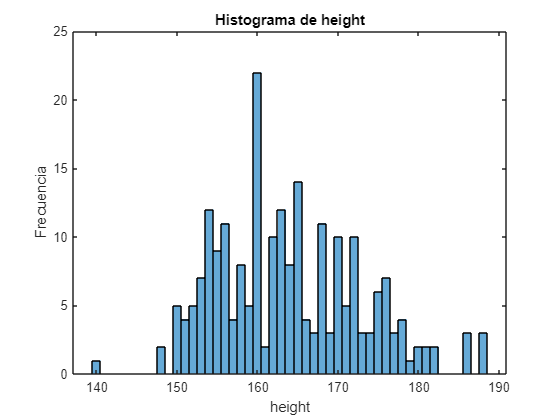

**Tabla de frecuencias para la variable weight:**


Valor mínimo de weight: 38


Valor máximo de weight: 96


Media de weight: 66.4823


Mediana de weight: 66


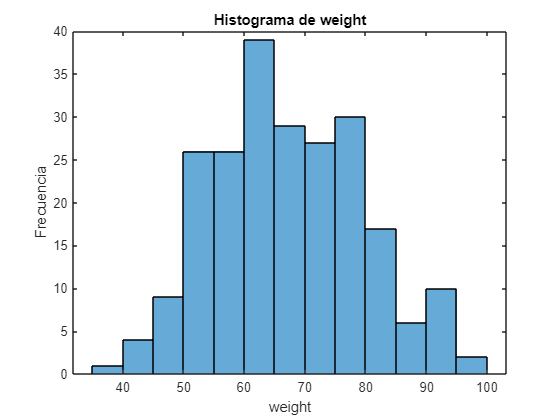

**Tabla de frecuencias para la variable age:**


Valor mínimo de age: 65


Valor máximo de age: 91


Media de age: 74.4779


Mediana de age: 74


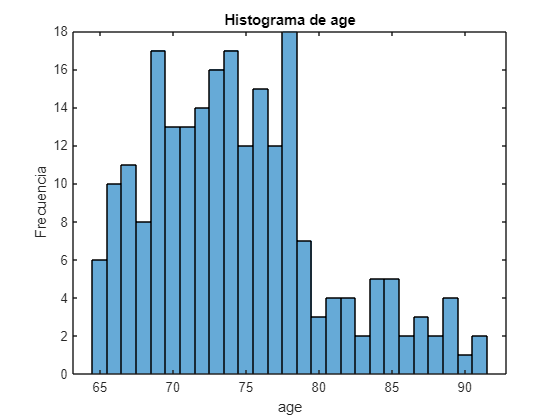

**Tabla de frecuencias para la variable meat:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     1
     3
    11
    83
    67
    61



Frecuencia relativa (%) 


    0.4425
    1.3274
    4.8673
   36.7257
   29.6460
   26.9912



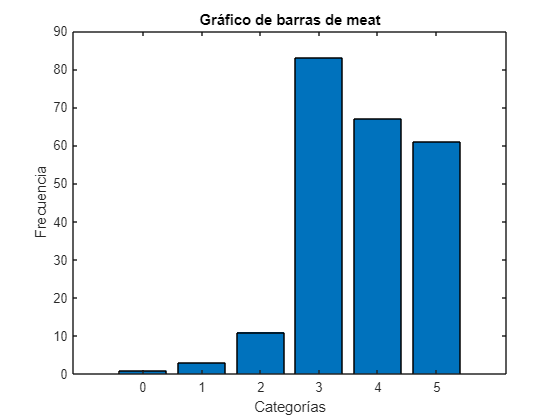

**Tabla de frecuencias para la variable fish:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     4
    21
    61
   118
    15
     7



Frecuencia relativa (%) 


    1.7699
    9.2920
   26.9912
   52.2124
    6.6372
    3.0973



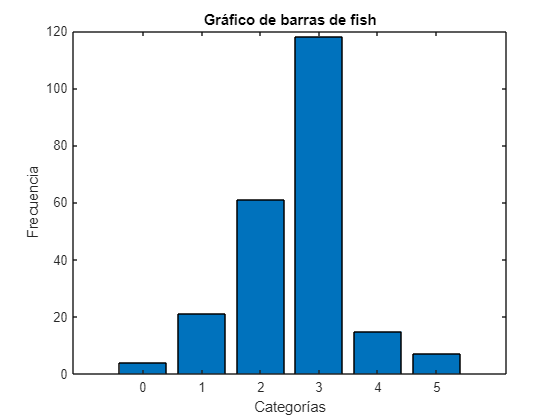

**Tabla de frecuencias para la variable raw_fruit:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     2
     8
     8
    14
    22
   172



Frecuencia relativa (%) 


    0.8850
    3.5398
    3.5398
    6.1947
    9.7345
   76.1062



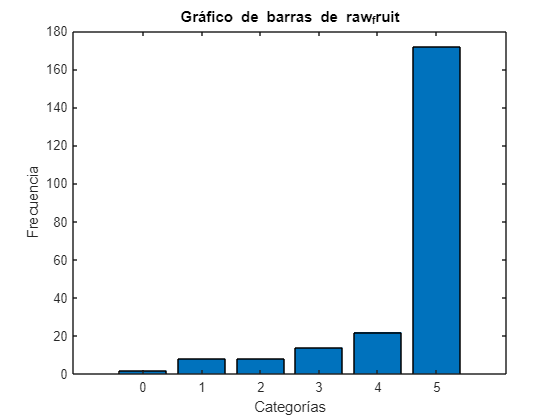

**Tabla de frecuencias para la variable cooked_fruit_veg:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


     2
     3
     7
    30
    36
   148



Frecuencia relativa (%) 


    0.8850
    1.3274
    3.0973
   13.2743
   15.9292
   65.4867



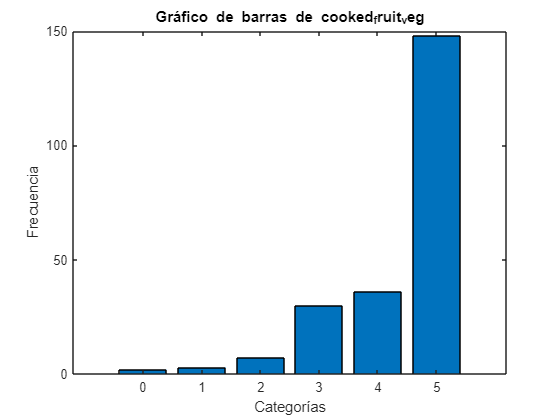

**Tabla de frecuencias para la variable chocol:**


Valores que toma la variable 


     0
     1
     2
     3
     4
     5



Frecuencia 


    50
    62
    16
    22
    11
    65



Frecuencia relativa (%) 


   22.1239
   27.4336
    7.0796
    9.7345
    4.8673
   28.7611



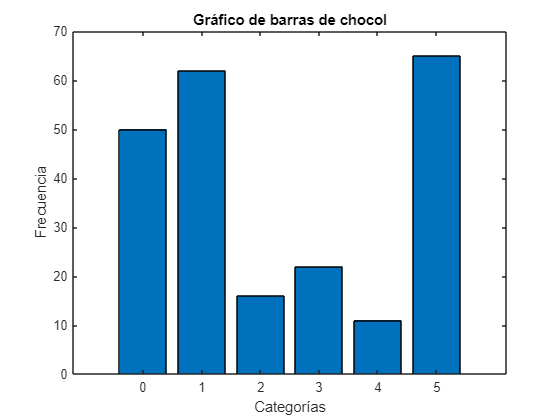

**Tabla de frecuencias para la variable fat:**


Valores que toma la variable 


     1
     2
     3
     4
     5
     6
     7
     8



Frecuencia 


    15
    27
    48
    68
    40
    23
     1
     4



Frecuencia relativa (%) 


    6.6372
   11.9469
   21.2389
   30.0885
   17.6991
   10.1770
    0.4425
    1.7699



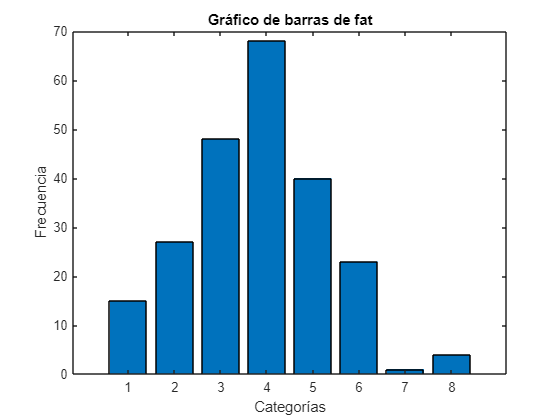

for i = 1:length(variables)
    if ismember(variables{i}, {'height', 'weight', 'age', 'tea', 'coffee'})
        % Para variables continuas, muestra estadísticas descriptivas y un histograma
        disp(['**Tabla de frecuencias para la variable ', variables{i}, ':**'])
        disp(['Valor mínimo de ', variables{i}, ': ', num2str(min(datos.(variables{i})))]);
        disp(['Valor máximo de ', variables{i}, ': ', num2str(max(datos.(variables{i})))]);
        disp(['Media de ', variables{i}, ': ', num2str(mean(datos.(variables{i})))]);
        disp(['Mediana de ', variables{i}, ': ', num2str(median(datos.(variables{i})))]);
        figure; % Crea una nueva figura
        histogram(datos.(variables{i}));
        title(['Histograma de ', variables{i}]); % Agrega un título al gráfico
        xlabel(variables{i}); % Etiqueta el eje x
        ylabel('Frecuencia'); % Etiqueta el eje y
    else
        % Para variables categóricas, muestra una tabla de frecuencias y un gráfico de barras
        tab = tabulate(datos.(variables{i}));
        disp(['**Tabla de frecuencias para la variable ', variables{i}, ':**']);
        disp('Valores que toma la variable ');
        disp(tab(:,1));
        disp('Frecuencia ');
        disp(tab(:,2));
        disp('Frecuencia relativa (%) ');
        disp(tab(:,3));
        figure; % Crea una nueva figura
        bar(tab(:,2))
        title(['Gráfico de barras de ', variables{i}]); % Agrega un título al gráfico
        xlabel('Categorías'); % Etiqueta el eje x
        ylabel('Frecuencia'); % Etiqueta el eje y
        set(gca, 'XTickLabel',tab(:,1)); % Asigna las etiquetas de las categorías al eje x
    end
end